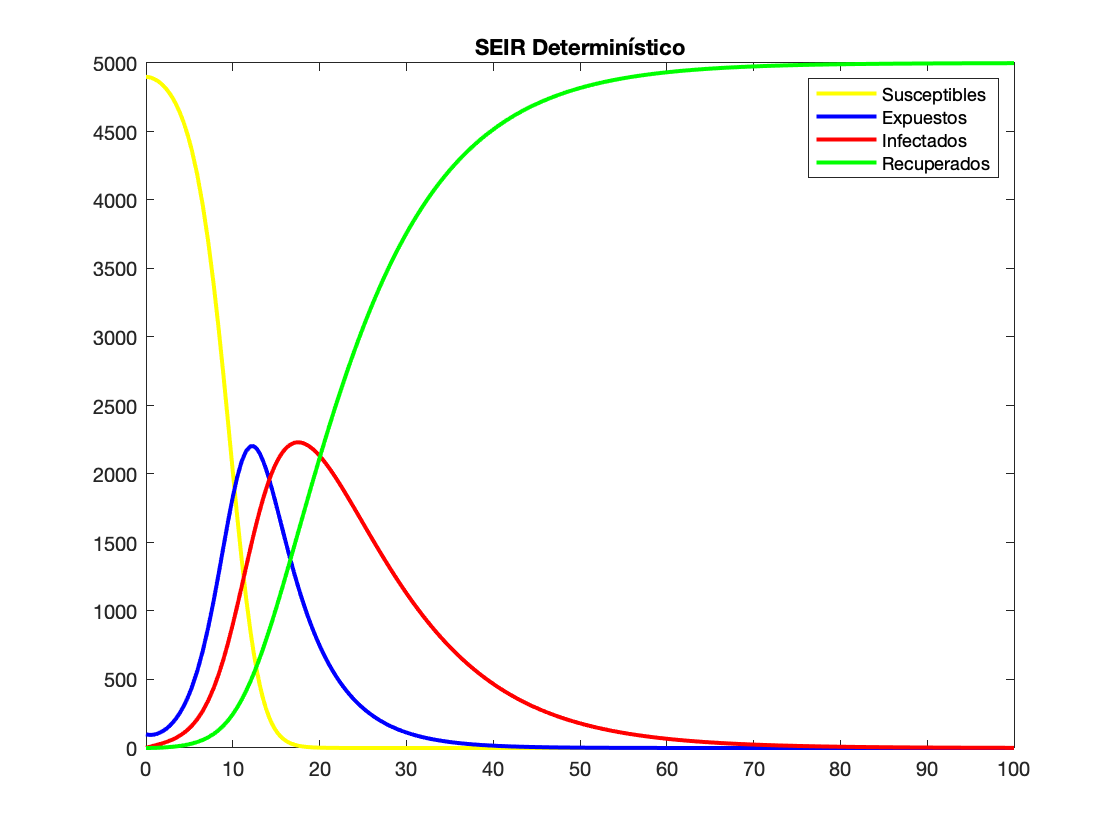


% a)
tspan = [0 100];

y0 = [4899 100 1 0 1.8 .1 .1895];

[tsol, ysol] = ode45(@SEIR_ODE,tspan, y0); 

plot(tsol,ysol(:, 1), 'Color','y', 'LineWidth',2)
hold on
plot(tsol,ysol(: ,2), 'Color','b','LineWidth',2)
plot(tsol, ysol(:, 3), 'Color','r','LineWidth',2)
plot(tsol, ysol(:, 4), 'Color','g','LineWidth',2)
legend("Susceptibles","Expuestos","Infectados","Recuperados")
title('SEIR Determinístico')
hold off

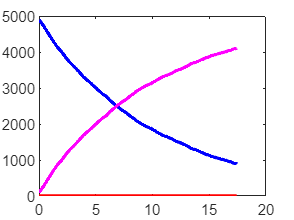

   %4. Doob Gillespie 
   
    beta = 1.8; % Tasa de transmisión
    sigma = 0.1; % Tasa de exposición
    gamma = 0.5; % Tasa de recuperación

    % Número inicial de individuos en la población
    N = 5000;

    % Condiciones iniciales
    S0 = 4899/N; % Fracción inicial de susceptibles
    E0 = 100/N; % Fracción inicial de expuestos
    I0 = 1/N;   % Fracción inicial de infectados
    R0 = 0;   % Fracción inicial de recuperados

    % Vector de condiciones iniciales
    y0 = [S0 * N; E0 * N; I0 * N; R0 * N];

    % Tiempo de simulación
    tmax = 20;
    tspan = [0 tmax];

    % Se inicializan vectores para almacenar resultados
    tiempo_simulacion = zeros(1, tmax);
    poblacion = zeros(4, tmax);

    tiempo_actual = 0;
    estado_actual = y0;
    iteracion = 1;

    while tiempo_actual < tmax
        % Tasas de cambio
        tasas = [beta * estado_actual(1) * estado_actual(3) / N;   % Tasa de transmisión
                 sigma * estado_actual(1);                          % Tasa de exposición
                 gamma * estado_actual(3);                          % Tasa de recuperación
                 0];                                               

        % Calcular tasa total
        tasa_total = sum(tasas);

        % Generar dos números aleatorios
        r1 = rand();
        r2 = rand();

        % Calcular tiempo hasta la próxima reacción
        tau = -log(r1) / tasa_total;

        % Se determina cúal reacción ocurrió
        j = find(cumsum(tasas) >= r2 * tasa_total, 1);

        estado_actual = estado_actual + actualizarEstado(j);
        tiempo_actual = tiempo_actual + tau;

        tiempo_simulacion(iteracion) = tiempo_actual;
        poblacion(:, iteracion) = estado_actual;

        % Incrementar el índice de iteración
        iteracion = iteracion + 1;
 

    % Graficar resultados
    plot(tiempo_simulacion, poblacion(1, :), 'b', 'LineWidth', 2); % Susceptibles
    hold on;
    plot(tiempo_simulacion, poblacion(2, :), 'm', 'LineWidth', 2); % Expuestos
    plot(tiempo_simulacion, poblacion(3, :), 'r', 'LineWidth', 2); % Infectados
    plot(tiempo_simulacion, poblacion(4, :), 'g', 'LineWidth', 2); % Recuperados

    title('Modelo SEIR Estocástico (Doob Gillespie)');
    xlabel('Tiempo');
    ylabel('Individuos');
    legend('Susceptibles', 'Expuestos', 'Infectados', 'Recuperados');
    grid on;
    hold off;
 end

    % Parámetros del modelo SEIR
    beta = 1.8; % Tasa de transmisión
    sigma = 0.1; % Tasa de exposición
    gamma = 0.5; % Tasa de recuperación

    % Número inicial de individuos en la población
    N = 5000;

    % Condiciones iniciales
    S0 = 4899/N; % Fracción inicial de susceptibles
    E0 = 100/N; % Fracción inicial de expuestos
    I0 = 1/N;   % Fracción inicial de infectados
    R0 = 0;   % Fracción inicial de recuperados

    % Tiempo de simulación
    tmax = 100;
    tspan = [0 tmax];

    % Configurar la simulación de Gillespie
    iteraciones = 10;
    poblacion_total = zeros(4, tmax, iteraciones);

    % Realizar 10 iteraciones
    for iteracion = 1:iteraciones
        % Vector de condiciones iniciales
        y0 = [S0 * N; E0 * N; I0 * N; R0 * N];

        % Inicializar vectores para almacenar resultados
        tiempo_simulacion = zeros(1, tmax);
        poblacion = zeros(4, tmax);

        tiempo_actual = 0;
        estado_actual = y0;
        tiempo_index = 1;

        while tiempo_actual < tmax
            % Resto del código de simulación (mismo que en el código anterior)
            tasas = [beta * estado_actual(1) * estado_actual(3) / N;   % Tasa de transmisión
                     sigma * estado_actual(1);                          % Tasa de exposición
                     gamma * estado_actual(3);                          % Tasa de recuperación
                     0];                                                % No hay tasa para los recuperados
            tasa_total = sum(tasas);
            r1 = rand();
            r2 = rand();
            tau = -log(r1) / tasa_total;
            j = find(cumsum(tasas) >= r2 * tasa_total, 1);
            estado_actual = estado_actual + actualizarEstado(j);
            tiempo_actual = tiempo_actual + tau;
            tiempo_simulacion(tiempo_index) = tiempo_actual;
            poblacion(:, tiempo_index) = estado_actual;
            tiempo_index = tiempo_index + 1;
        end

        % Almacenar resultados de la iteración actual
        poblacion_total(:, :, iteracion) = poblacion;
    end

    % Graficar resultados superpuestos
    figure;
    hold on;
    for iteracion = 1:iteraciones
        plot(tiempo_simulacion, poblacion_total(1, :, iteracion), 'y', 'LineWidth', 1); % Susceptibles
        plot(tiempo_simulacion, poblacion_total(2, :, iteracion), 'b', 'LineWidth', 1); % Expuestos
        plot(tiempo_simulacion, poblacion_total(3, :, iteracion), 'r', 'LineWidth', 1); % Infectados
        plot(tiempo_simulacion, poblacion_total(4, :, iteracion), 'g', 'LineWidth', 1); % Recuperados
    end
    
    plot(tsol,ysol(: ,2), 'Color','b','LineWidth',3)
    plot(tsol, ysol(:, 3), 'Color','r','LineWidth',3)
    plot(tsol, ysol(:, 4), 'Color','g','LineWidth',3)
    title('Modelo SEIR Estocástico (Simulación de Gillespie)');
    xlabel('Tiempo');
    ylabel('Número de Individuos');
    legend('S (DB)', 'E (DB)', 'I (DB)', 'R (DB)',"S (ode45)",'E (ode45)', 'I (ode45)', 'R (ode45)');
    grid on;
    hold off;


function cambio = actualizarEstado(j)
    % Función para actualizar el estado según la reacción j
    switch j
        case 1
            cambio = [-1; 1; 0; 0];
        case 2
            cambio = [-1; 1; 0; 0];
        case 3
            cambio = [0; -1; 1; 0];
        otherwise
            cambio = [0; 0; 0; 0];
    end
end

function dYdt = SEIR_ODE(t ,Y)
beta = Y(5);
gamma = Y(6);
sigma= Y(7);

S = Y(1);
E= Y(2);
I = Y(3);
R = Y(4);

N= S+E+I+R;

dSdt = -(beta*S*I)/N;
dEdt= (beta*S*I)/N-sigma*E;
dIdt = sigma*E - gamma*I;
dRdt = gamma*I;
dYdt = [dSdt;dEdt;dIdt;dRdt; 0; 0;0];
end
